# 第三章 形态学图像处理

## 二值图像形态学

【例3-1】请编写MATLAB程序，实现对二值图像经行腐蚀、膨胀、开、闭运算

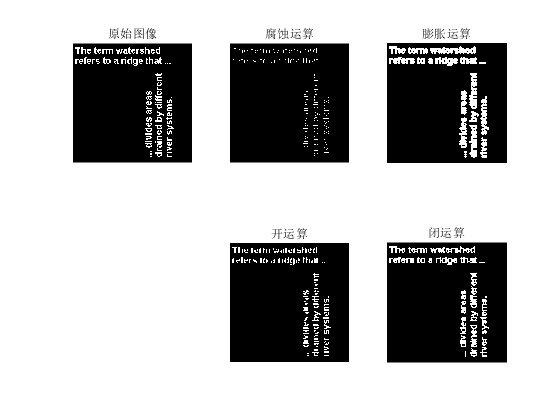

%读入及显示凸显
I=imread('text.png');
%选取结构元素
se=strel('diamond',1);
i2=imerode(I,se);%腐蚀
i3=imdilate(I,se);%膨胀
i4=imdilate(i2,se);%开运算
i5=imerode(i3,se);%闭运算

figure;
subplot(2,3,1);
imshow(I);
title("原始图像");
subplot(2,3,2);
imshow(i2)
title("腐蚀运算");
subplot(2,3,3);
imshow(i3)
title("膨胀运算");
subplot(2,3,5);
imshow(i4);
title("开运算")
subplot(2,3,6);
imshow(i5);
title("闭运算");

## 边缘提取、骨架抽取、细化和粗化

【例3-2】请编写MATLAB程序，实现对原始图像进行边缘提取、骨架抽取、细化和粗化运算

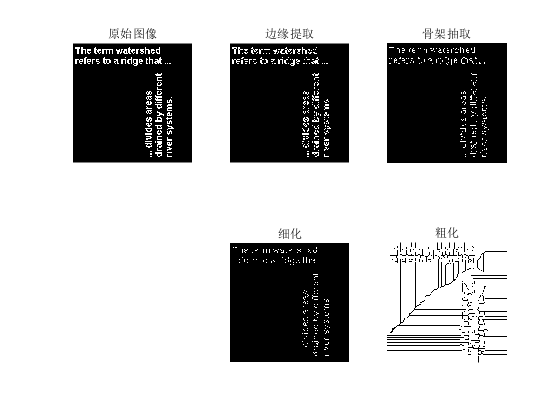

I=imread('text.png');
i1=bwmorph(I,'remove');%边缘提取
i2=bwmorph(I,'skel',inf);
i3=bwmorph(I,'thin',inf);
i4=bwmorph(I,'thicken',inf);
figure()
subplot(2,3,1)
imshow(I);
title("原始图像");
subplot(2,3,2)
imshow(i1);
title("边缘提取")
subplot(2,3,3)
imshow(i2)
title("骨架抽取")
subplot(2,3,5)
imshow(i3)
title("细化")
subplot(2,3,6)
imshow(i4)
title("粗化");

## 形态学滤波

【例3-3】请编写MATLAB程序，实现图像的形态学滤波

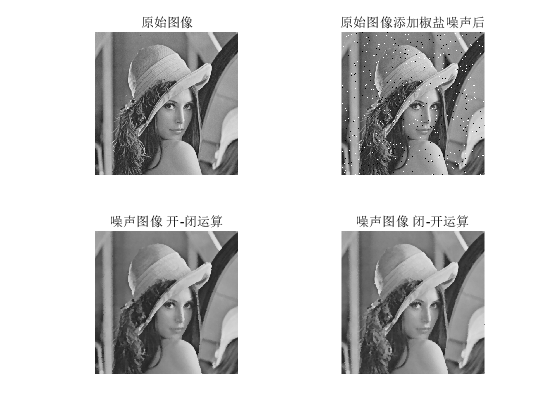

I=imread("lena512.bmp");
f = imnoise(I,'salt & pepper',0.02);
se=strel("disk",2);
f1=imopen(f,se);
f2=imclose(f1,se);
f3=imclose(f,se);
f4=imopen(f3,se);
figure;
subplot(2,2,1)
imshow(I);title("原始图像");
subplot(2,2,2)
imshow(f);title("原始图像添加椒盐噪声后");
subplot(2,2,3)
imshow(f2);title("噪声图像 开-闭运算");
subplot(2,2,4)
imshow(f4);title("噪声图像 闭-开运算");